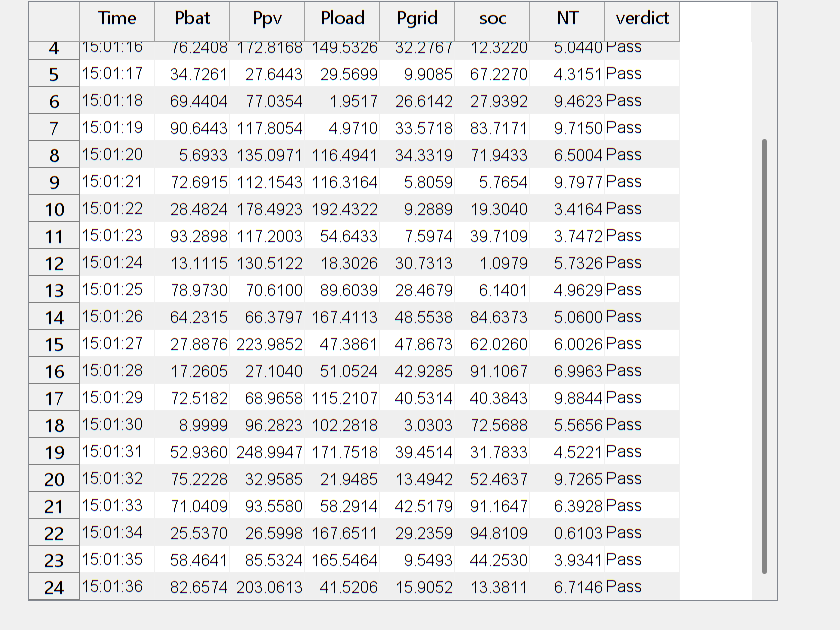


delay=1;
%table init
figure;
columnNames = {'Time','Pbat', 'Ppv', 'Pload', 'Pgrid', 'soc', 'NT', 'verdict'};
T = table([], [], [], [], [], [], [], [], 'VariableNames', columnNames);

% Create the initial uitable
tHandle = uitable(gcf, 'Data', table2cell(T), 'ColumnName', columnNames, 'Position', [20 20 500 400]);


for i=1:24
%     payload=strcat('{"fFQLimit":',char(string(soc(i))),'}');
%     InverterObj.send(payload)
%     LB.setRealPower(1,load(i));
%     fprintf("Load set  = %d ,  and SOC is set to =  %d : \n",load(i),soc(i))

     %set scenario


     %get parameters




     %perform evaluation



     %tabulate

     % Sample data for the new row (replace with actual data as needed)
    newRow = {datestr(now,'hh:mm:ss'), rand()*100, rand()*300, rand()*200, rand()*50, rand()*100, rand()*10, 'Pass'};  % Example random data
    
    % Convert the new row to a table
    newRowTable = cell2table(newRow, 'VariableNames', columnNames);
    
    % Append the new row to the table
    T = [T; newRowTable]; 
    
    % Update the uitable with the new data
    tHandle.Data = table2cell(T); 
    pause(delay)
end